### Desire Path generation

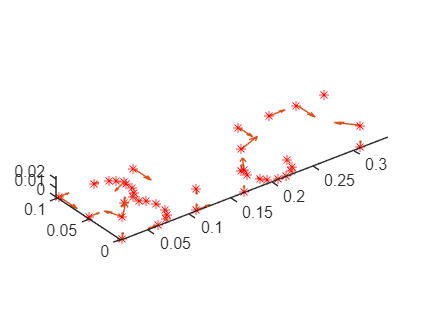

clear,clc;
load hershey
letter_1 = hershey{'B'};
letter_2 = hershey{'L'};
letter_3 = hershey{'J'};
letter_4 = hershey{'T'};
scale = 0.12;
moving_up = 0.2*scale;

p1 = [scale*letter_1.stroke; zeros(1,size(letter_1.stroke,2))];
k = find(isnan(p1(1,:)));
p1(:,k) = p1(:,k-1); p1(3,k) = moving_up;

p2 = [scale*letter_2.stroke; zeros(1,size(letter_2.stroke,2))];
k = find(isnan(p2(1,:)));
p2(:,k) = p2(:,k-1); p2(3,k) = moving_up;

p3 = [scale*letter_3.stroke; zeros(1,size(letter_3.stroke,2))];
k = find(isnan(p3(1,:)));
p3(:,k) = p3(:,k-1); p3(3,k) = moving_up;

p4 = [scale*letter_4.stroke; zeros(1,size(letter_4.stroke,2))];
k = find(isnan(p4(1,:)));
p4(:,k) = p4(:,k-1); p4(3,k) = moving_up;



% shift the second letter to the left
distance = 0.75*scale;
p2(1,:) = p2(1,:) + distance;

% shift the third letter to the left
distance = 2*0.75*scale;
p3(1,:) = p3(1,:) + distance;

% shift the fourth letter to the left
distance = 3*0.75*scale;
p4(1,:) = p4(1,:) + distance;

% create intermediate via points between letter
p_middle =[[p1(1,end) p1(2,end) moving_up];[p2(1,1) p2(2,1) 0]]';
p_middle2 =[[p2(1,end) p2(2,end) moving_up];[p3(1,1) p3(2,1) 0]]';
p_middle3 =[[p3(1,end) p3(2,end) moving_up];[p4(1,1) p4(2,1) 0]]';

% Concatenate the waypoint
p = [p1 p_middle p2 p_middle2 p3 p_middle3 p4];



figure
plot3(p(1,:),p(2,:),p(3,:),"*r");
hold on
quiver3(p(1,1:(end-1)),p(2,1:(end-1)),p(3,1:(end-1)),diff(p(1,:)),diff(p(2,:)),diff(p(3,:)))
axis equal

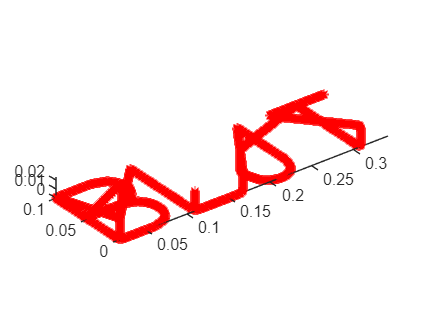


% figure
% plot(p(:,1),p(:,2),"*r")
% axis equal

% generate the trajectory
% sample time
dt = 0.01;
axis_speed_limit =0.5*scale;
acceleration_time = 0.2;
traj = mstraj(p(:,1:end)',[axis_speed_limit axis_speed_limit axis_speed_limit],[],p(:,1)',dt,acceleration_time);
figure
plot3(traj(:,1),traj(:,2),traj(:,3),"*r")
axis equal

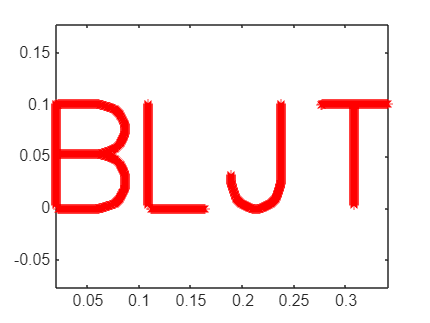


% filter out the plot the result on 2D
filtered_2D_point =[];
index =1;
for i = 1:1:length(traj)
    if (traj(i,3)<0.0001)
        filtered_2D_point(index,1) = traj(i,1);
        filtered_2D_point(index,2) = traj(i,2);
        index = index +1;
    end
end

figure
plot(filtered_2D_point(:,1),filtered_2D_point(:,2),"*r")
axis equal


% offset so that the when the joints are in zero position
% the EF is at the start point of the trajectory
%Position of the EF in meter:
xEF = 0.6443968;
yEF = 0;
zEF = 0.1492202;


X_offset = traj(1,1) - xEF ; 
Y_offset = traj(1,2) - yEF;
Z_offset = traj(1,3) - zEF;

traj_offset = traj;
traj_offset(:,1) = traj_offset(:,1) - X_offset; %postion for the pentip match with the start point of trajectory
traj_offset(:,2) = traj_offset(:,2) - Y_offset;
traj_offset(:,3) = traj_offset(:,3) - Z_offset;

% create the input data for simulink
time = 0:dt:(dt*(length(traj_offset)-1));
trajectory_time = [time' traj_offset];


% reduce the resolution for trajectory display
theshold_filter_m =0.001;
traj_offset_display(1,1) =traj_offset(1,1);
traj_offset_display(1,2) =traj_offset(1,2);
traj_offset_display(1,3) =traj_offset(1,3);
idx =1;
for i=2:1:length(traj_offset)
    if ((abs(traj_offset(i,1)-traj_offset_display(idx,1)) > theshold_filter_m) || ...
        (abs(traj_offset(i,2)-traj_offset_display(idx,2)) > theshold_filter_m) || ...
        (abs(traj_offset(i,3)-traj_offset_display(idx,3)) > theshold_filter_m))

        idx =idx +1;
        traj_offset_display(idx,1) =traj_offset(i,1);
        traj_offset_display(idx,2) =traj_offset(i,2);
        traj_offset_display(idx,3) =traj_offset(i,3);
    end
    save('traj_data.mat','trajectory_time');
    t_end = trajectory_time(end,1);

end